# GReS - Understanding the Mesh

## Introduction

This tutorial introduces you to the basic GReS features to input a mesh, visualize it and manage the output of a simple simulation. 

cd(fullfile(gres_root,'Tutorial','meshInput'))

## VTK file format

GReS supports two mesh file formats, `.vtk and .msh.` In this example, you will see how to read a mesh representing a simple cube. The [VTK](https://vtk.org/doc/nightly/html/index.html) (Visualization ToolKit) format is a widely used format for storing mesh and scientific data. It supports both ASCII and binary encoding and can represent structured and unstructured meshes. It is especially well-suited for visualization with tools such as ParaView or VisIt. The `.vtk` files can include point coordinates, connectivity (cells), cell types, and optional scalar or vector data for post-processing or visualization. Here is an example of a simple VTK file [Box.vtk](matlab:open('./Mesh\Box.vtk')).

**HEADER**

The file begins with a standard VTK header:

**In the current version of the code, this is the only admitted header for a vtk file. If you try to input a file where the above informations are different, GReS will throw an error.**

**POINTS**

This section lists 8 vertices deifning the corners of the cube, each with x, y, z coordinates:

**CELLS**

There are 3 cells:

The first two are quadrilaterals (4-node faces).

The third is a hexahedron (8-node volume).

The second number, 19, is the total number of integers appearing in the section:

3 cell definitions: (1×5) + (1×5) + (1×9) = 19 integers

**CELL_TYPES** 

This section characterizes each cell with an integer corresponding to the shape.

9 = quadrilateral (used for surfaces)

12 = hexahedron (used for the volume)

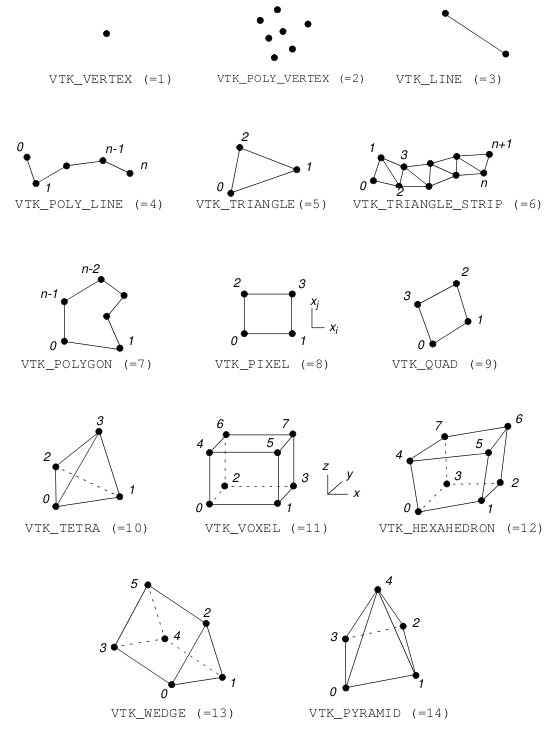

**CELL_DATA**

This scalar field assigns an ID to each cell.

The top and bottom faces have different IDs (1 and 2). The volume has ID 1.

These IDs are very useful to identify different regions of the grid where to impose boundary condition. 

## MSH file format

The .msh format is the native format of [GMSH](https://gmsh.info/doc/texinfo/gmsh.html), a powerful and open-source mesh generator. For the unit cube shown before, this is what the input file looks like.

**GReS only supports .msh file of version 2.2, which is not the latest one. **

We refer the user to the Gmsh tutorial for a detailed description of the .msh file format and how to use it for generating a grid. Note that the `.msh` file supports name for the cell or surface region under the `$PhysicalNames` section

## Reading a mesh in GReS

To read a mesh, you first need to create a `Mesh` object.

msh = Mesh();

If we print the object

msh

msh =   Mesh with properties:

               nDim: 0
             nNodes: 0
             nCells: 0
          nSurfaces: 0
             nEdges: 0
        coordinates: []
              cells: []
            cellTag: []
           nCellTag: []
       cellNumVerts: []
       cellCentroid: []
    surfaceCentroid: []
         cellVolume: []
        surfaceArea: []
           surfaces: []
         surfaceTag: []
        nSurfaceTag: []
    surfaceNumVerts: []
              edges: []
            edgeTag: []
       edgeNumVerts: []
           cartGrid: 0
        cellRegions: []
     surfaceRegions: []
        cellVTKType: []
     surfaceVTKType: []
        edgeVTKType: []
           meshType: 'Unstructured'


we see that this object contain numerous properties still to be defined. 

To populate this properties, call the `importMesh() `method with the name of the mesh file.

msh.importMesh('Mesh/Box.vtk');

The file name must have either '.vtk' or '.msh' extension, so that GReS knows how to read the file. The path to the file is always relative to the location of the main file.

*Under the hood, GReS is using compiled C++ *[*mex function*](https://www.mathworks.com/help/matlab/call-mex-file-functions.html)* to read the grid. Take a look at the Setup tutorial to see how to compile c++ code and produce mex files before starting using it.*

Now print again the msh object

msh

msh =   Mesh with properties:

               nDim: 3
             nNodes: 8
             nCells: 1
          nSurfaces: 2
             nEdges: 0
        coordinates: [8×3 double]
              cells: [1 2 3 4 5 6 7 8]
            cellTag: 1
           nCellTag: 1
       cellNumVerts: 8
       cellCentroid: []
    surfaceCentroid: []
         cellVolume: []
        surfaceArea: []
           surfaces: [2×4 double]
         surfaceTag: [2×1 double]
        nSurfaceTag: 2
    surfaceNumVerts: [2×1 double]
              edges: []
            edgeTag: [0×1 double]
       edgeNumVerts: [0×1 double]
           cartGrid: 0
        cellRegions: []
     surfaceRegions: []
        cellVTKType: 12
     surfaceVTKType: [2×1 double]
        edgeVTKType: [0×1 double]
           meshType: 'Unstructured'


The mesh is a 3D mesh (`nDim=3`) with 8 nodes, 1 cell and 2 surfaces. Notice the difference between the 6 geometrical surfaces of the cube and the 2 surfaces defined in Box.vtk.

`coordinates` contains the three coordinates of the nodes, while `cells` is the connectivity matrix listing the nodes belonging to each cell. Here, the matrix reduces to only a row vector since only one cell is defined. `surfaces` contains the topological information of the cells.

The information delivered by the CELL_DATA section is stored in the vectors `cellTag` and` surfaceTag`. CELL TYPE section of the vtk file is stored in the vectors `cellVTKType` and` surfaceVTKType`. 

Let's now import the .msh version of the grid and see the differences.

msh.importMesh('Mesh/Box.msh');
msh

msh =   Mesh with properties:

               nDim: 3
             nNodes: 8
             nCells: 1
          nSurfaces: 2
             nEdges: 0
        coordinates: [8×3 double]
              cells: [1 2 3 4 5 6 7 8]
            cellTag: 1
           nCellTag: 1
       cellNumVerts: 8
       cellCentroid: []
    surfaceCentroid: []
         cellVolume: []
        surfaceArea: []
           surfaces: [2×4 double]
         surfaceTag: [2×1 double]
        nSurfaceTag: 2
    surfaceNumVerts: [2×1 double]
              edges: []
            edgeTag: [0×1 double]
       edgeNumVerts: [0×1 double]
           cartGrid: 0
        cellRegions: [1×1 struct]
     surfaceRegions: [1×1 struct]
        cellVTKType: 12
     surfaceVTKType: [2×1 double]
        edgeVTKType: [0×1 double]
           meshType: 'Unstructured'


As expected, all the information are the same. You may notice that the `cellRegions` and `surfaceRegion` properties are empty. Although they do not have any practical importance in a GReS simulation, they may be useful for the user to see to which part of the grid each tag is referring to. In order to set them to match the $PhysicalNames, use the following method to read the mesh. 

msh.importGMSHmesh('Mesh/Box.msh');
msh

msh =   Mesh with properties:

               nDim: 3
             nNodes: 8
             nCells: 1
          nSurfaces: 2
             nEdges: 0
        coordinates: [8×3 double]
              cells: [1 2 3 4 5 6 7 8]
            cellTag: 1
           nCellTag: 1
       cellNumVerts: 8
       cellCentroid: []
    surfaceCentroid: []
         cellVolume: []
        surfaceArea: []
           surfaces: [2×4 double]
         surfaceTag: [2×1 double]
        nSurfaceTag: 2
    surfaceNumVerts: [2×1 double]
              edges: []
            edgeTag: [0×1 double]
       edgeNumVerts: [0×1 double]
           cartGrid: 0
        cellRegions: [1×1 struct]
     surfaceRegions: [1×1 struct]
        cellVTKType: 12
     surfaceVTKType: [2×1 double]
        edgeVTKType: [0×1 double]
           meshType: 'Unstructured'


## A more advanced example

Let's now import a more complicated grid, the one used in the [DeepAquifer](matlab:open('..\..\Tests\Deep_Aquifer\ReservoirTest_Hexa.msh')) test case. 

mshAdvanced = Mesh();
mshAdvanced.importMesh('Mesh/Reservoir.msh')
mshAdvanced

mshAdvanced =   Mesh with properties:

               nDim: 3
             nNodes: 3509
             nCells: 2800
          nSurfaces: 2120
             nEdges: 0
        coordinates: [3509×3 double]
              cells: [2800×8 double]
            cellTag: [2800×1 double]
           nCellTag: 3
       cellNumVerts: [2800×1 double]
       cellCentroid: []
    surfaceCentroid: []
         cellVolume: []
        surfaceArea: []
           surfaces: [2120×4 double]
         surfaceTag: [2120×1 double]
        nSurfaceTag: 5
    surfaceNumVerts: [2120×1 double]
              edges: []
            edgeTag: []
       edgeNumVerts: []
           cartGrid: 0
        cellRegions: [1×1 struct]
     surfaceRegions: [1×1 struct]
        cellVTKType: [2800×1 double]
     surfaceVTKType: [2120×1 double]
        edgeVTKType: []
           meshType: 'Unstructured'


Check out the workspace to inspect the properties of `mshAdvanced`. This object contains many `cellTag` and `surfaceTag`.

### Cell properties

From the above example, you may notice that some properties as `cellArea` and `surfaceArea` are still empty. To compute them, we need to instaciate an `Elements` object

nG = 2;
elems = Elements(msh,nG);

This class internally uses Gauss quadrature to compute some geometrical properties and populates the mesh objects being passed in input. 

Now, we can access other properties

msh.cellCentroid

ans =     0.5000    0.5000    0.5000


msh.cellVolume

ans = 1.0000

msh.surfaceArea

ans =      1
     1


## **Creating structured grids**

GReS provides also fast ways to generate simple structured cartesian grids, without the need of reading from external mesh files.

The command 

strMesh = structuredMesh(10,5,3,[0 50],[-10 40],[0 6])

strMesh =   Mesh with properties:

               nDim: 3
             nNodes: 264
             nCells: 150
          nSurfaces: 190
             nEdges: 0
        coordinates: [264×3 double]
              cells: [150×8 double]
            cellTag: [150×1 double]
           nCellTag: 1
       cellNumVerts: [150×1 double]
       cellCentroid: []
    surfaceCentroid: []
         cellVolume: []
        surfaceArea: []
           surfaces: [190×4 double]
         surfaceTag: [190×1 double]
        nSurfaceTag: 6
    surfaceNumVerts: [190×1 double]
              edges: []
            edgeTag: []
       edgeNumVerts: []
           cartGrid: 0
        cellRegions: []
     surfaceRegions: []
        cellVTKType: [150×1 double]
     surfaceVTKType: [190×1 double]
        edgeVTKType: []
           meshType: 'Unstructured'


creates a cartesian mesh with 10 elements along the x-direction, 5 along the y-direction and 3 along the z-direction. The limiting coordinates of the grid are specified by the remaining 1x2 input arrays. Hence, this grid is a box going from 0 to 50 along x, from -10 to 40 along y, and from 0 to 6 along z.

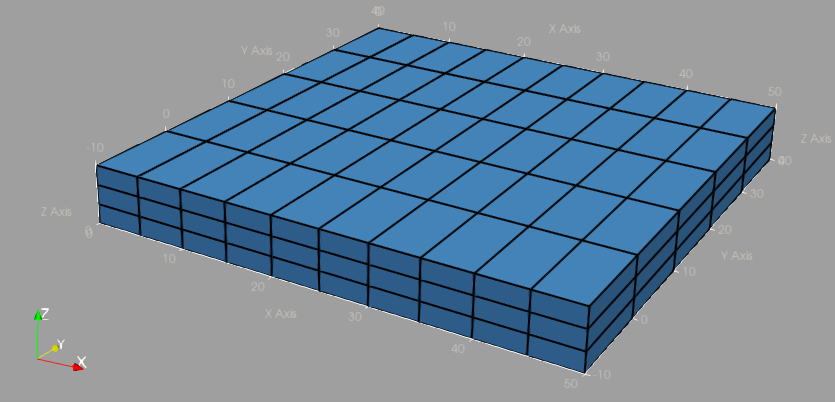

We can also create structured grids with non-uniform spacing of the nodes along the axis. We simply input 3 arrays of the coordinates of the nodes along x,y and z. 

xv = [0 5 15 20 25 27.5 30 31 32 38 43 50];
yv = [-10 0 10 20 25 30 40];
zv = [0 2 3 4 6];

strMesh = structuredMesh(xv,yv,zv)

strMesh =   Mesh with properties:

               nDim: 3
             nNodes: 420
             nCells: 264
          nSurfaces: 268
             nEdges: 0
        coordinates: [420×3 double]
              cells: [264×8 double]
            cellTag: [264×1 double]
           nCellTag: 1
       cellNumVerts: [264×1 double]
       cellCentroid: []
    surfaceCentroid: []
         cellVolume: []
        surfaceArea: []
           surfaces: [268×4 double]
         surfaceTag: [268×1 double]
        nSurfaceTag: 6
    surfaceNumVerts: [268×1 double]
              edges: []
            edgeTag: []
       edgeNumVerts: []
           cartGrid: 0
        cellRegions: []
     surfaceRegions: []
        cellVTKType: [264×1 double]
     surfaceVTKType: [268×1 double]
        edgeVTKType: []
           meshType: 'Unstructured'


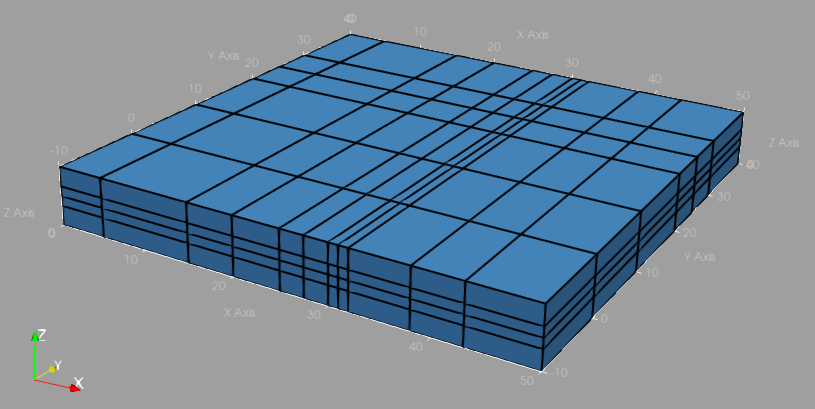

## **Creating Non-conforming structured grids**

GReS is capable of working with non-conforming grids! To create simple non-conforming grids, you can generate a BlockStructured grid made from different structured blocks of variable mesh size. Each block (indexed with classical i-j-k pattern), can be refined independently using an octree stategy. 

We first define the base grid (left figure) creating a  `BlockStructuredMesh` object.

b = BlockStructuredMesh(2,2,2,[0 1],[0 1],[0 1],3);
b.refineRecursive([1 1 1],2);
b.refineRecursive([2 2 2],3);
b.refineRecursive([2 1 2],1);

That is, a simple unit cube with 8 cells (left figure).  Compared to the standard structuredMesh, we have one additional input representing the maximum level of refinement of the base grid. 

We then use the refineRecursive method to refine the sub-blocks in position (1,1,1), (2,1,2) and (2,2,2)  specify the depth of the refinements (centre figure).

b.refineRecursive([1 1 1],2);
b.refineRecursive([2 2 2],3);
b.refineRecursive([2 1 2],1);

Finally, we further refine the the second block (2,1,1) of the already refined base block (2,1,2) (right figure).

b.refineRecursive([2 1 2],2,2)
blockStructuredMesh = b.processGeometry()

blockStructuredMesh =   Mesh with properties:

               nDim: 3
             nNodes: 936
             nCells: 596
          nSurfaces: 550
             nEdges: 0
        coordinates: [936×3 double]
              cells: [596×8 double]
            cellTag: [596×1 double]
           nCellTag: 1
       cellNumVerts: [596×1 double]
       cellCentroid: []
    surfaceCentroid: []
         cellVolume: []
        surfaceArea: []
           surfaces: [550×4 double]
         surfaceTag: [550×1 double]
        nSurfaceTag: 8
    surfaceNumVerts: [550×1 double]
              edges: []
            edgeTag: []
       edgeNumVerts: []
           cartGrid: 0
        cellRegions: []
     surfaceRegions: []
        cellVTKType: [596×1 double]
     surfaceVTKType: [550×1 double]
        edgeVTKType: []
           meshType: "Unstructured"


When we are done with recursive refinement, we need to call the processGeometry() method to produce a valid GReS Mesh() object.  You can inspect the resulting grid plotting its geometry in paraview, calling 

plotMesh(blockStructuredMesh,'Mesh/blockStructuredPlot')

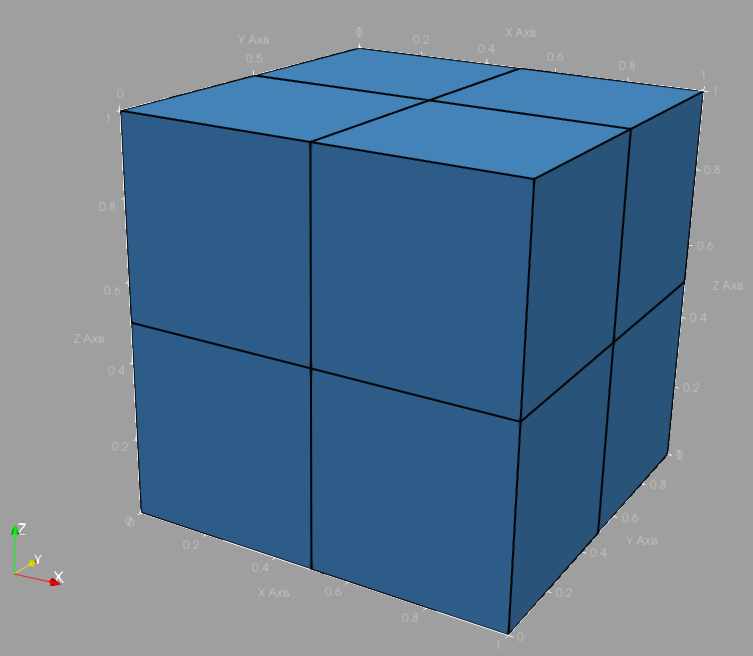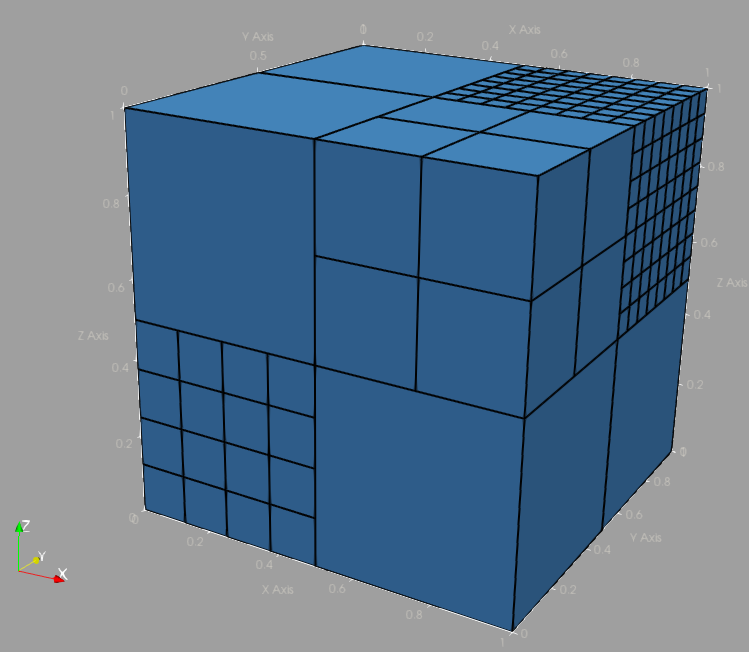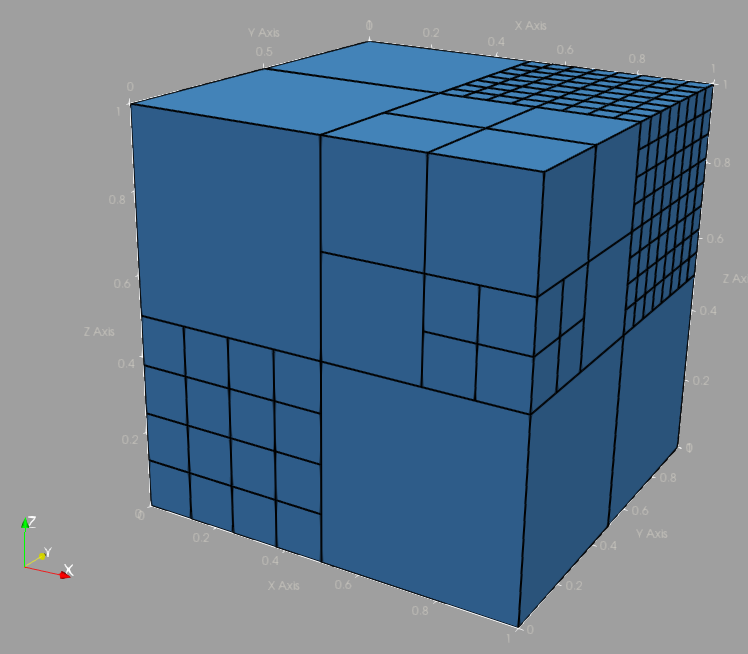

and inspecting the vtm file stores in the '*blockStructuredPlot' *output folder. 

## Grid structure

The Mesh() object alone does not provide all the geometrical informations required to discretize a problem in GReS. Therefore, GReS requires the user to work with a structure built as

The Elements() object in the 'cells' field is always required to compute additional geometrical properties of the grid, such as cell volume, and centroid, as well as to manage the finite element computation in case finite elements are used. 

The 'faces' field instead, is only requiredfor Finite Volumes simulations. 